in_to_m = @(in) in*0.0254;

phi = 0;
W = in_to_m(4);
D = in_to_m(2);
L = in_to_m(1);
rho_full = 1250;
rho_water = 1000;

disp_ratio = 0.25;
percent_infill = disp_ratio * (rho_water)/(rho_full);
f_rho_dynamic = @(y, h) ( (y >= h)*0.5*rho_full + (y < h)*rho_full );
f_rho_const = @(y, h) (percent_infill * rho_full);
dividers_0 = [D/3, 2*D/3];
densities_0 = rho_full * [0.95, 0.5, 0.1];
x_0 = [W, D, dividers_0, densities_0];

f_cost = generate_cost_func(f_contour_quadratic);
A = eye(length(x_0));
A(3:4, 2) = -1;
A = [A; -1 * eye(length(x_0))];
b = [in_to_m(6); in_to_m(3); 0; 0; rho_full; rho_full; rho_full; zeros(length(x_0), 1)];

tic
[min_params, min_avs_error] = fmincon(f_cost, x_0, A, b);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


disp(min_avs_error);

     1



toc

Elapsed time is 107.831517 seconds.


## Simulate Boat:

f_rho = generate_density_func(min_params(3:4), min_params(5:7));
f_simulate = @(phi)(boat_sim(phi, min_params(1), min_params(2), L, f_contour_quadratic, f_rho, true));

### Flat boat:

phi = 0;
f_simulate(phi);
title(sprintf("Boat simulation at \\phi = %d\\circ", phi))

### Heeled boat:

phi = 15;
f_simulate(phi);
title(sprintf("Boat simulation at \\phi = %d\\circ", phi))

### Heeled boat at AVS:

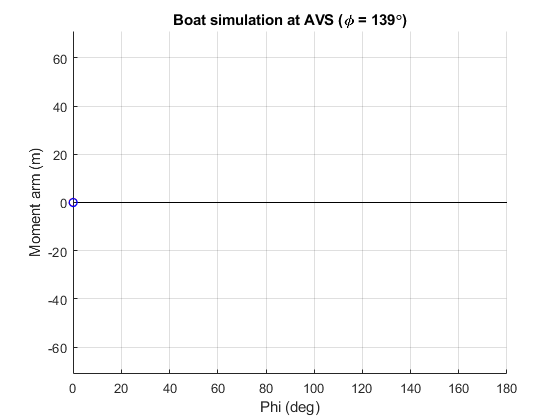

phi = calc_avs(min_params(1), min_params(2), L, f_contour_quadratic, f_rho);
f_simulate(phi);
title(sprintf("Boat simulation at AVS (\\phi = %d\\circ)", phi))

### AVS Curve

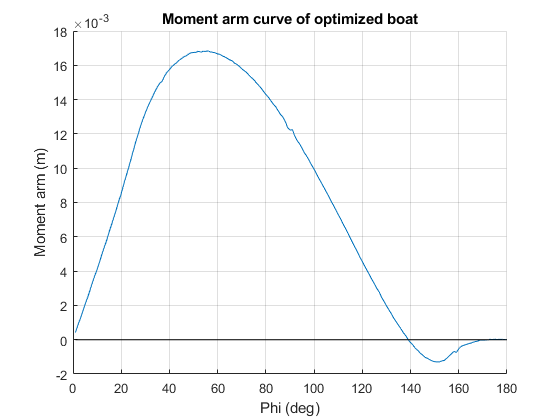

[avs, v_phis, v_moment_arms] = calc_avs(min_params(1), min_params(2), L, f_contour_quadratic, f_rho);

figure();
hold on;

plot(v_phis, v_moment_arms);
line([min(v_phis), max(v_phis)], [0, 0], 'color',' black');

grid on;
title("Moment arm curve of optimized boat")
xlabel("Phi (deg)");
ylabel("Moment arm (m)")

### Infill densities:

min_params(5:7) / rho_full * 100

ans =        86.054           50       14.198


function [mat_W, mat_D, mat_avs] = param_sweep(v_w, v_d, f_contour, f_rho)
    [mat_W, mat_D] = meshgrid(v_w, v_d);
    
    v_points = [mat_W(:), mat_D(:)];
    v_avs = zeros(length(v_points), 1);
    L = 1;
    for i = 1 : length(v_points)
        try
            v_avs(i) = calc_avs(v_points(i, 1), v_points(i, 2), L, f_contour, f_rho);
        catch exception
            % Check for the case of undefined AVS
            if strcmp(exception.identifier, 'MATLAB:fzero:ValuesAtEndPtsSameSign')
                fprintf("AVS undefined at [w, d] = [%f, %f]\n", v_points(i, 1), v_points(i, 2));
                v_avs(i) = 0;
            else
                % Otherwise throw error
                fprintf("Error at params [%f, %f]", v_points(i, 1), v_points(i, 2));
                throw(exception)
            end            
            
        end
    end
    mat_avs = reshape(v_avs, size(mat_W));
end

function [f_rho] = generate_density_func(dividers, densities)
    densities = abs(densities);
    f_rho = @(y)( (y <= dividers(1))*densities(1) + ...
            (y > dividers(1) & y <= dividers(2))*densities(2) + ...
            (y > dividers(2))*densities(3) );
end

function f_cost = generate_cost_func(f_contour)
    L = 1;
    f_cost = @(params) abs(140 - calc_avs(params(1), params(2), L, f_contour, generate_density_func(params(3:4), params(5:7))));
end
